# Explore events by location

Explore the damage costs and path of storm events on a map of the United States. 

Functionality within [Mapping Toolbox](https://www.mathworks.com/help/map/) is helpful for working with geospatial data and includes many data analysis visualization options.

clear 
load prepEvents

## Explore the damage costs of tornadoes by location

Select the tornadoes from the table and associated locations and damage cost.

idx = data.event_type == 'Tornado';
tornadoes = data(idx,:);
lat = tornadoes.begin_lat;
lon = tornadoes.begin_lon;
damage = tornadoes.damage_total;

Plot the data as scatter plot on a map of the United States with color representing the total damage. Create a large figure window to enhance the the visualization (see bottom of this script for `bigFigure` function)

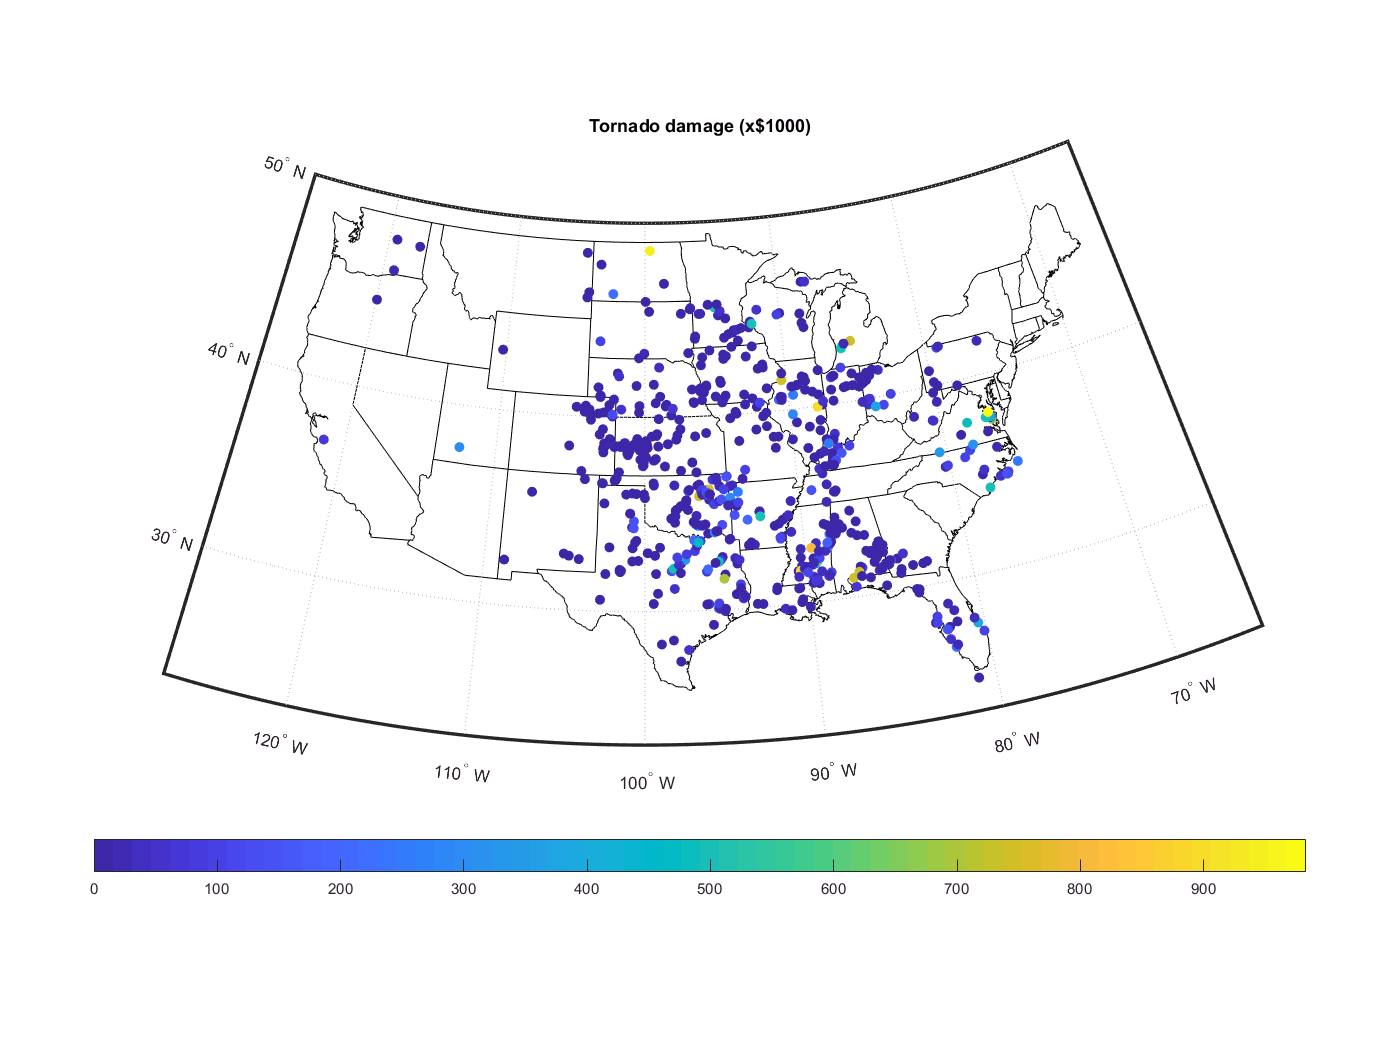

bigFigure;
usamap('conus')
geoshow('usastatelo.shp','FaceColor','w')
scatterm(lat,lon,[],damage,'filled')
colorbar('southoutside')
title('Tornado damage (x$1000)')

## Visualize directions of tornadoes

Determine the distance each event traveled and convert the units. 

d_m = distance(data.begin_lat,data.begin_lon,...
    data.end_lat,data.end_lon,wgs84Ellipsoid);
d_mi = d_m*unitsratio('mi','m');

Visualize the path of tornadoes with a quiver plot to illustrate direction and scale on the map. (Note that the length of the quivers indicate direction and relative magnitude but may not indicate the exact locations when the plot is scaled. The plotm function can be used to keep the start and end points at the correct locations, shown in the last section below)

delt_lat = tornadoes.begin_lat - tornadoes.end_lat;
delt_lon = tornadoes.begin_lon - tornadoes.end_lon;

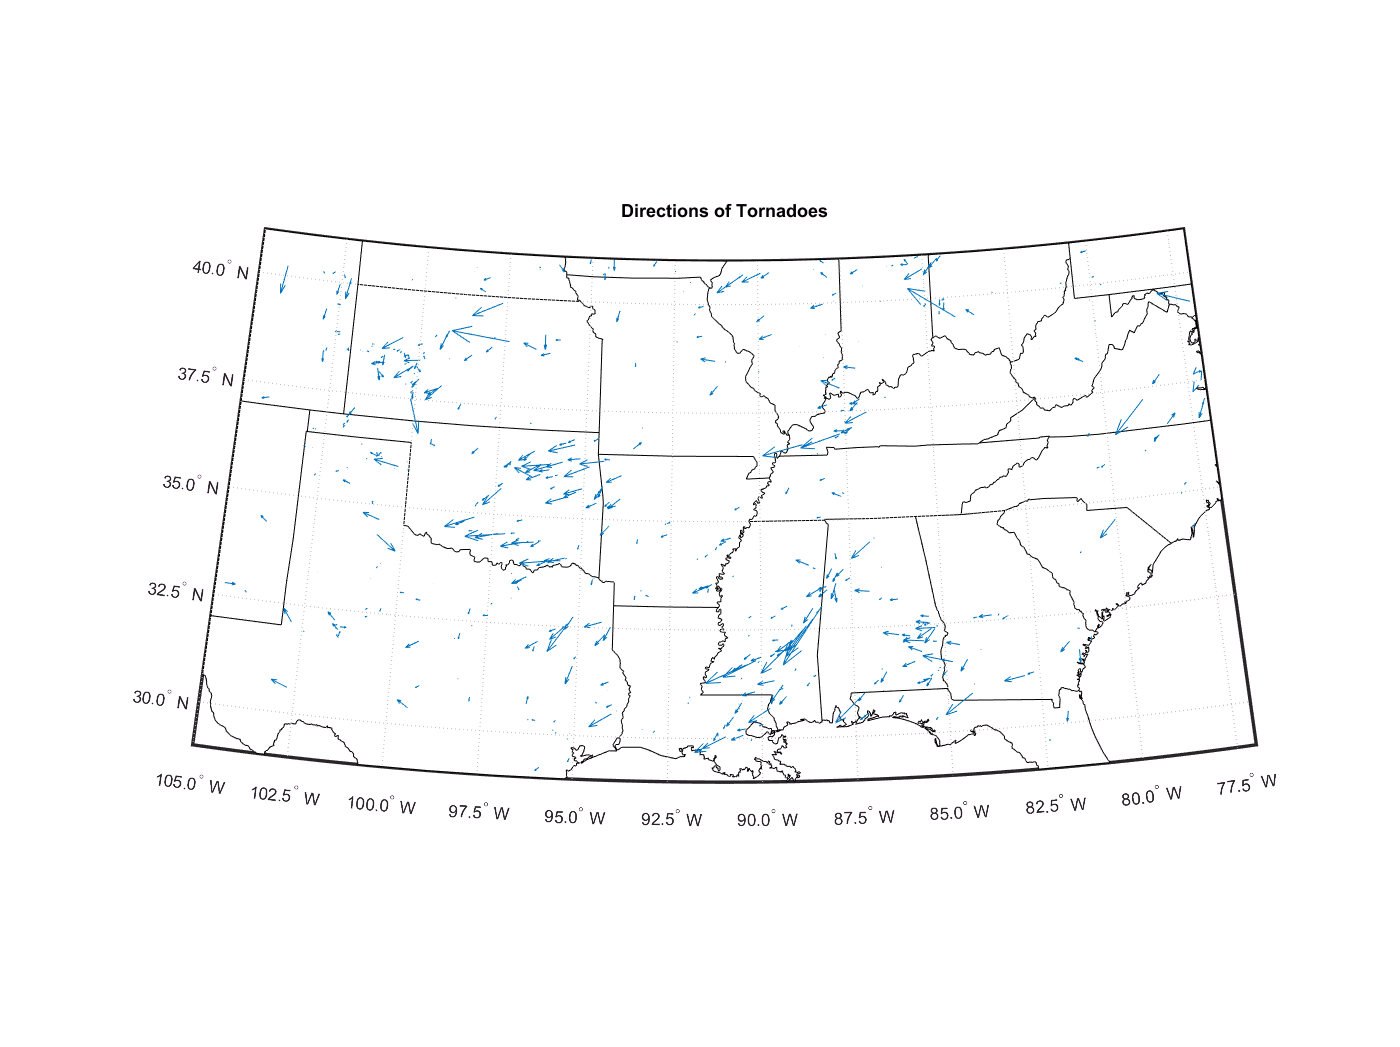

bigFigure;
usamap([29 41],[-105 -77]);
geoshow('usastatelo.shp','FaceColor','w');
h = quiverm(tornadoes.begin_lat,tornadoes.begin_lon,...
    delt_lat,delt_lon);
title('Directions of Tornadoes')

## Visualize directions of moving weather events

Visualize additional types of moving events with different colors.

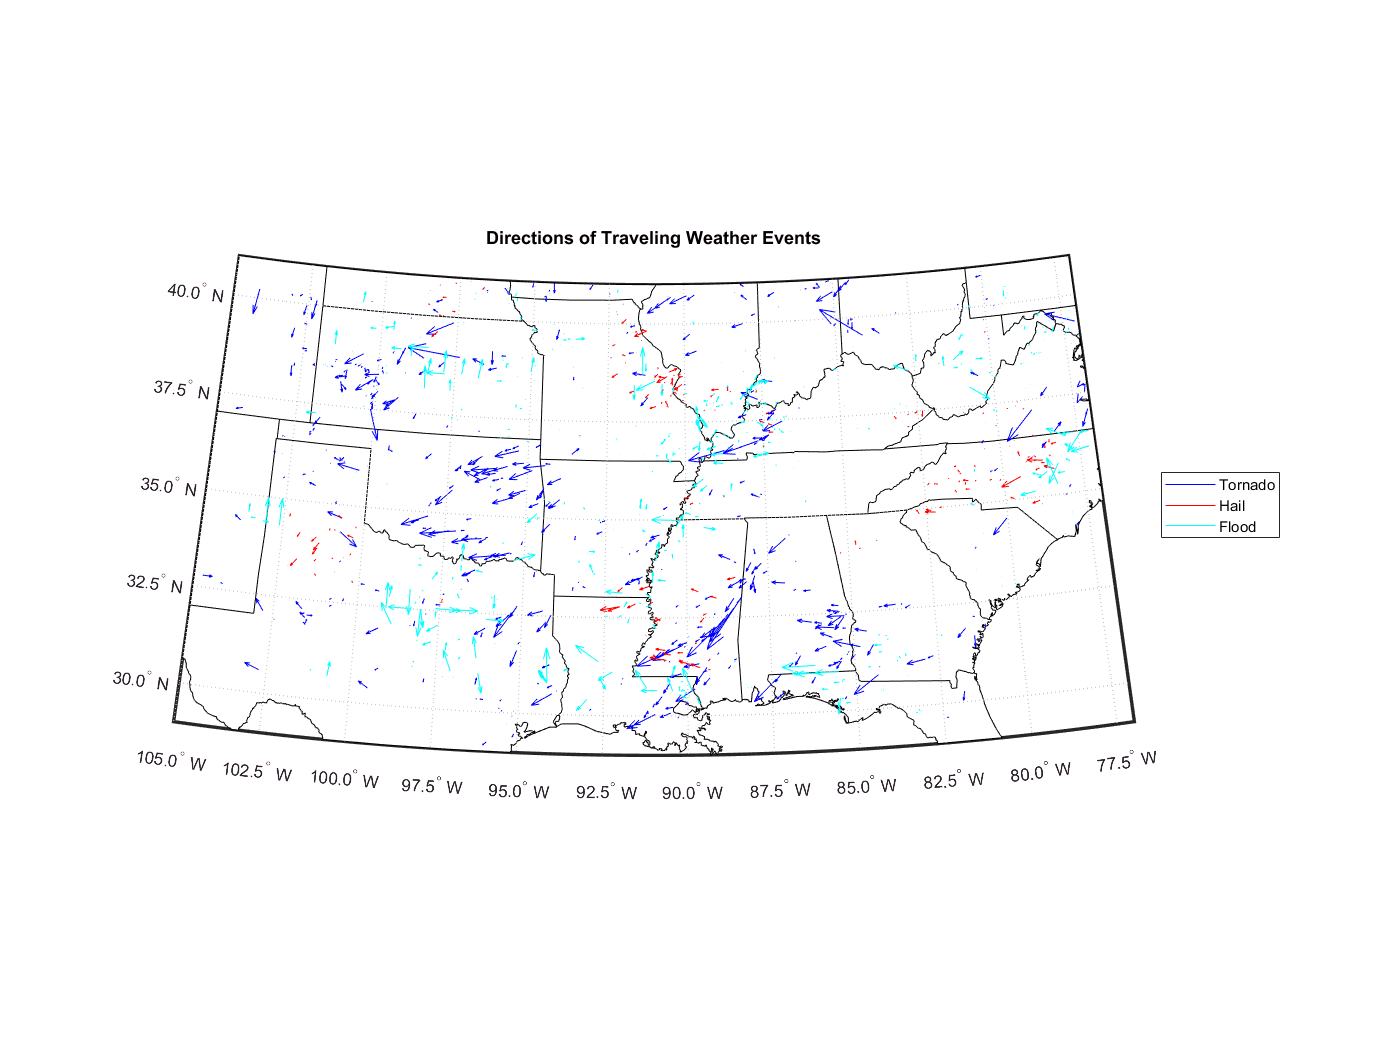

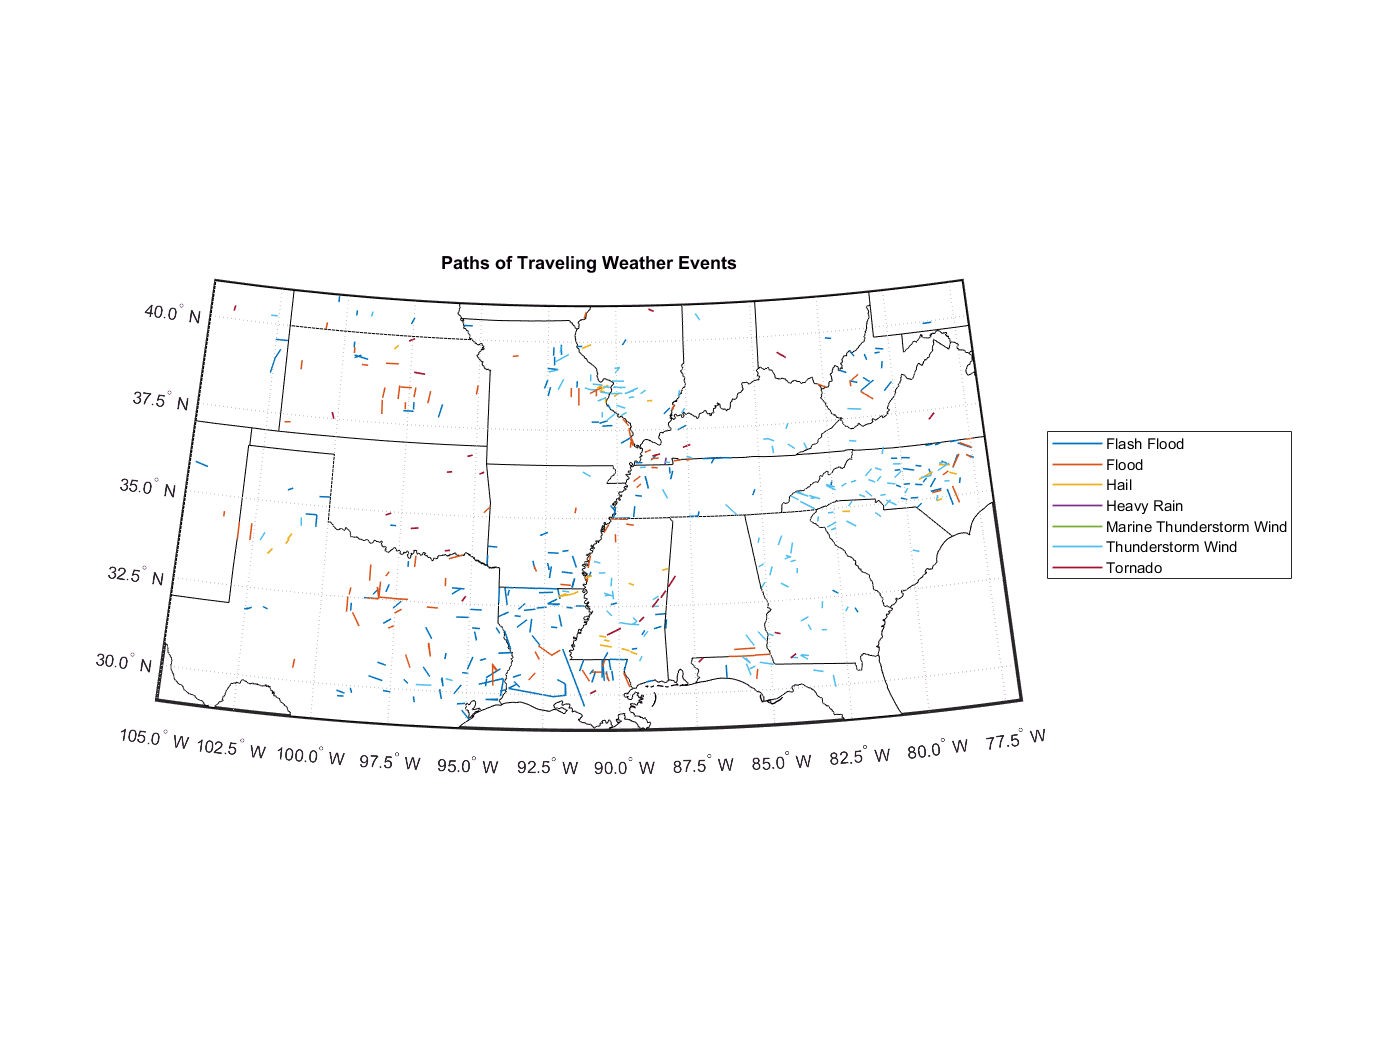

ev = {'Tornado','Hail','Flood'};
col = {'b','r','c'};
bigFigure;
a = usamap([29 41],[-105 -77]);
geoshow('usastatelo.shp','FaceColor','w');
p = gobjects(1,numel(ev));
for ii = 1:length(ev)
    idx = data.event_type == ev{ii};
    delt_lat = data.begin_lat(idx) - data.end_lat(idx);
    delt_lon = data.begin_lon(idx) - data.end_lon(idx);
    h = quiverm(data.begin_lat(idx),data.begin_lon(idx),...
        delt_lat,delt_lon,col{ii});
    p(ii) = h(1);
end
legend(p,ev,'Location','EastOutside')
title('Directions of Traveling Weather Events')

## Helper funs

function f = bigFigure
    f = figure;
    f.Position = f.Position.*[1 1 2 2];
end

function plotMovingWeatherEvents(lat,lon,eventtypes)
eventtypes = removecats(eventtypes);
eventcats = categories(eventtypes);
bigFigure;
usamap([29 41],[-105 -77]);
geoshow('usastatehi.shp','FaceColor','w');
ax = gca;
hold on
eventcolors = ax.ColorOrder;
p = gobjects(1,numel(eventcats));
for ii = 1:numel(eventcats)
    idx = eventtypes == eventcats(ii);
    latplot = lat(:,idx);
    lonplot = lon(:,idx);
    p(ii) = plotm(latplot(:),lonplot(:),...
        'LineWidth',1);
    p(ii).Color = eventcolors(ii,:);

end
legend(p,eventcats,'Location','eastoutside')
hold off
end
